Load and Visualize ECG (Baseline)

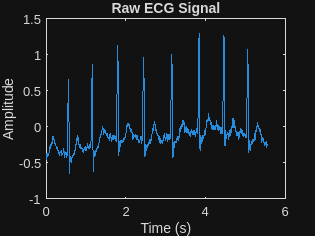

clc; clear; close all;

load('/MATLAB Drive/Examples/R2025b/predmaint_shared/ExampleECGSignalExample/ecg.mat');
fs = 360;

t = (0:length(ecg)-1)/fs;

figure;
plot(t, ecg);
title('Raw ECG Signal');
xlabel('Time (s)');
ylabel('Amplitude');

Filtering

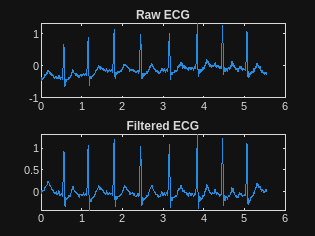

hp_cutoff = 0.5;  % Hz
[b1, a1] = butter(2, hp_cutoff/(fs/2), 'high');
ecg_hp = filtfilt(b1, a1, ecg);
lp_cutoff = 40;  % Hz
[b2, a2] = butter(4, lp_cutoff/(fs/2), 'low');
ecg_filtered = filtfilt(b2, a2, ecg_hp);

figure;

subplot(2,1,1);
plot(t, ecg);
title('Raw ECG');

subplot(2,1,2);
plot(t, ecg_filtered);
title('Filtered ECG');

R-Peak Detection

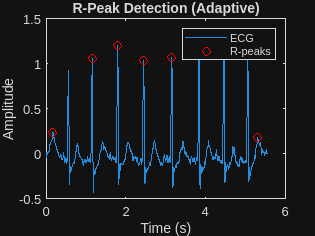

threshold = mean(ecg_filtered) + 0.6 * std(ecg_filtered);

min_distance = round(0.6 * fs);

[peaks, locs] = findpeaks(ecg_filtered, ...
    'MinPeakHeight', threshold, ...
    'MinPeakDistance', min_distance);

figure;
plot(t, ecg_filtered); hold on;
plot(t(locs), peaks, 'ro');
title('R-Peak Detection (Adaptive)');
xlabel('Time (s)');
ylabel('Amplitude');
legend('ECG', 'R-peaks');

Heart Rate (BPM)

RR_intervals = diff(locs) / fs;

BPM = 60 ./ RR_intervals;

avg_BPM = mean(BPM);

fprintf('Average Heart Rate: %.2f BPM\n', avg_BPM);

Average Heart Rate: 83.80 BPM


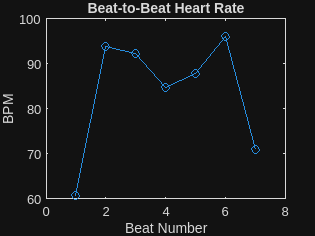


figure;
plot(BPM, '-o');
title('Beat-to-Beat Heart Rate');
xlabel('Beat Number');
ylabel('BPM');

Classification

if avg_BPM < 60
    condition = 'Bradycardia';
elseif avg_BPM > 100
    condition = 'Tachycardia';
else
    condition = 'Normal';
end

fprintf('Condition: %s\n', condition);

Condition: Normal


Final Visualization

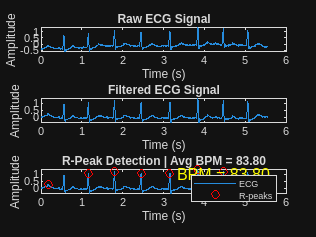

figure;

subplot(3,1,1);
plot(t, ecg);
title('Raw ECG Signal');
xlabel('Time (s)');
ylabel('Amplitude');

subplot(3,1,2);
plot(t, ecg_filtered);
title('Filtered ECG Signal');
xlabel('Time (s)');
ylabel('Amplitude');

subplot(3,1,3);
plot(t, ecg_filtered); hold on;
plot(t(locs), peaks, 'ro');

title(['R-Peak Detection | Avg BPM = ' num2str(avg_BPM, '%.2f')]);
xlabel('Time (s)');
ylabel('Amplitude');
legend('ECG', 'R-peaks');

text(t(end)*0.6, max(ecg_filtered)*0.8, ...
    ['BPM = ' num2str(avg_BPM, '%.2f')], ...
    'Color', 'yellow', 'FontSize', 12);

fprintf('\n--- FINAL RESULT ---\n');


--- FINAL RESULT ---


fprintf('Average Heart Rate: %.2f BPM\n', avg_BPM);

Average Heart Rate: 83.80 BPM


fprintf('Condition: %s\n', condition);

Condition: Normal
